% Ashwin Foucault Q6 %
%--------------------%
% N.B. Signal Processing Toolbox is required!

clear

format long

L = 67;
% Omega = 2*pi/86164; 
% sigma = pi/180*(140); 
% m = 28; 
% R_E = 6371000;
% g = 9.81;
% R = 8.5*1e-2; 
% mu = 1.81*1e-5; 
% 
% %gamma = 0.00000; 
% gamma = 6*pi*mu*R;
% K = Omega*cos(sigma);

tic
 
% Defines RHS of coupled ODEs
function state = fsolver(t,u)

L = 67;
Omega = 2*pi/86164; 
sigma = pi/180*(140); 
m = 28; 
R_E = 6371000;
g = 9.81;
R = 8.5*1e-2; 
mu = 1.81*1e-5; 

%gamma = 0.00000; 
gamma = 6*pi*mu*R;

K = Omega*cos(sigma);

state = zeros(4,1); 

state(1:2) = u(3:4); 
z = -sqrt(L^2-(u(1))^2-(u(2))^2); 
zdot = -(u(1)*u(3) + u(2)*u(4))/(z);

Eqx = 2*K*u(4) + ((Omega)^2)*R_E*cos(sigma)*sin(sigma) - gamma/m*u(3); 
Eqy = -2*Omega*sin(sigma)*zdot - 2*K*u(3) - gamma/m*u(4); 
Eqz = 2*Omega*sin(sigma)*u(4) - g - gamma/m*zdot; 

xddot = 1/(L^2 + (u(1))^2 + (u(2))^2)*(Eqx*(L^2 + (u(2))^2 - (u(1))^2) - 2*Eqy*u(1)*u(2) - Eqz*u(1)*z + (u(1)/z^2)*((u(3)*u(2) - u(4)*u(1))^2 - L^2*((u(3))^2 + (u(4))^2))); 
yddot = 1/(L^2 + (u(1))^2 + (u(2))^2)*(Eqy*(L^2 - (u(2))^2 + (u(1))^2) - 2*Eqx*u(1)*u(2) - Eqz*u(2)*z + (u(2)/z^2)*((u(3)*u(2) - u(4)*u(1))^2 - L^2*((u(3))^2 + (u(4))^2))); 

state(3:4) = [xddot; yddot]; 

end

% Defines initial conditions [x0; y0; vx0; vy0]
state_init = [3;0;0;0]; 

% Defines timespan(s)
N = 200000

N =       200000


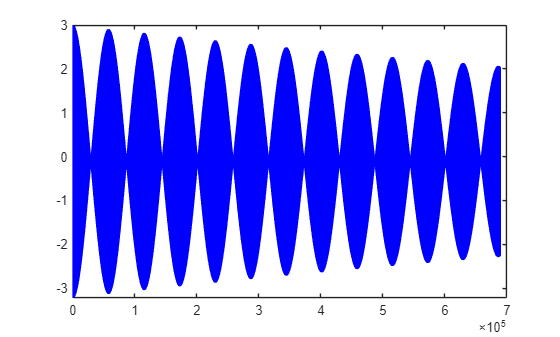

tspan = linspace(0,8*86164,N);

% Solves ODEs 
opts = odeset('RelTol',1e-10,'AbsTol',1e-10);
[t, state] = ode45(@fsolver, tspan, state_init, opts);

% Defines x, y, z positions and horizontal radial distance 
xs = state(:,1);
ys = state(:,2);
zs = -sqrt(L^2-(xs).^2-(ys).^2);
rs = sqrt(xs.^2+ys.^2);

% Defines x, y, z velocities and squared magnitude of velocity
xdots = state(:,3);
ydots = state(:,4);
zdots = (xs.*xdots + ys.*ydots)./(-zs);
vels_sq = xdots.^2 + ydots.^2 + zdots.^2;


% Creates upper and lower envelopes for the (generally) rapidly oscillating
% xs and ys 
[E_xs_upper,E_xs_lower] = envelope(xs,10,'peak');
[E_ys_upper,E_ys_lower] = envelope(ys,10,'peak'); 

[E_rs_upper,E_rs_lower] = envelope(rs,60,'peak');
[rpeaks,rlocs] = findpeaks(E_rs_upper, "MinPeakProminence", 0.005);
%rpeaks = [E_rs_upper(5); rpeaks]
%rlocs = [1; rlocs]


E_xs = zeros(2,N);
E_ys = zeros(2,N);
E_xs(1,:) = E_xs_upper;
E_xs(2,:) = E_xs_lower;
E_ys(1,:) = E_ys_upper;
E_ys(2,:) = E_ys_lower;


clf

plot(tspan, xs,"b")
ylim([min(xs),max(xs)])

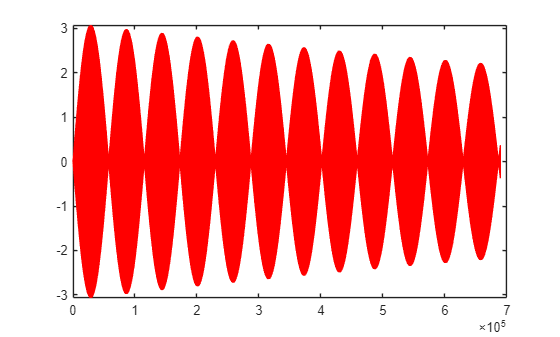

plot(tspan, ys,"r")
ylim([min(ys),max(ys)])

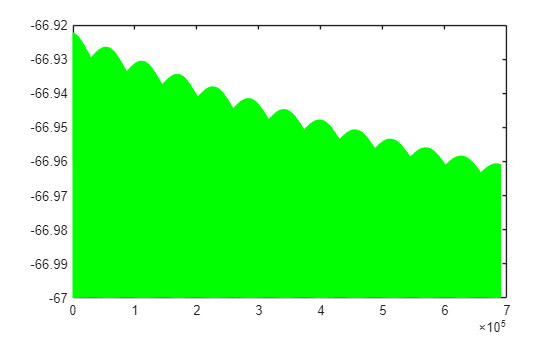

plot(tspan, zs,"g")

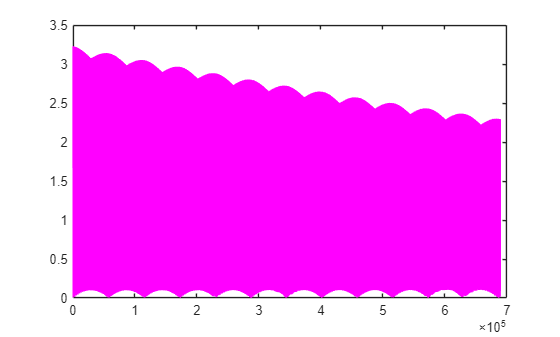

plot(tspan, rs,"m")

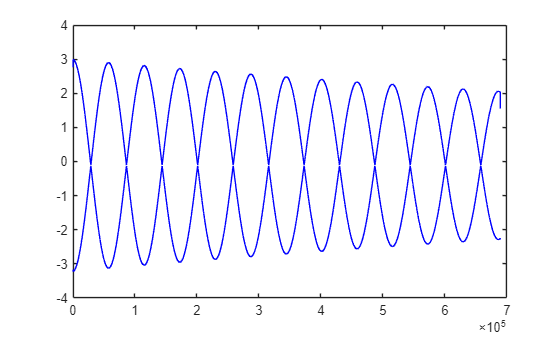



plot(tspan, E_xs_upper, "b", tspan, E_xs_lower, "b")

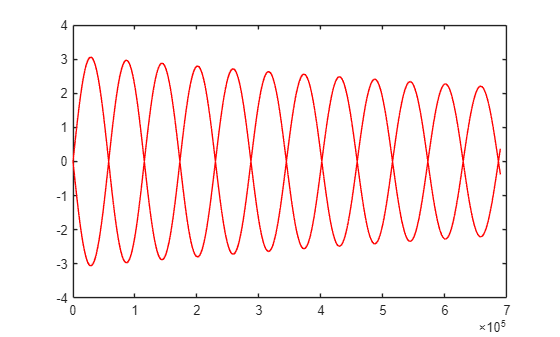

plot(tspan, E_ys_upper, "r", tspan, E_ys_lower, "r")


tees = zeros(1,length(rlocs));
for i=1:length(rlocs)
    tees(i) = tspan(rlocs(i));
end

tees

tees = 1.0e+05 *

   0.529669989149946   1.102146467532338   1.676690892254461   2.257990608353042   2.824883631618158   3.399496987884939   3.970525903829519   4.547827590337952   5.115513326366631   5.682957801989009   6.257743487117436   6.829909773548868


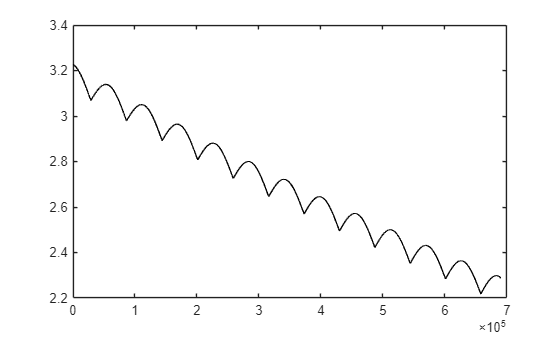


if length(tees) > 1
tl = [tees(1), tees(end)];
lrl = [log(rpeaks(1)), log(rpeaks(end))];
end

plot(tspan, E_rs_upper, "k")

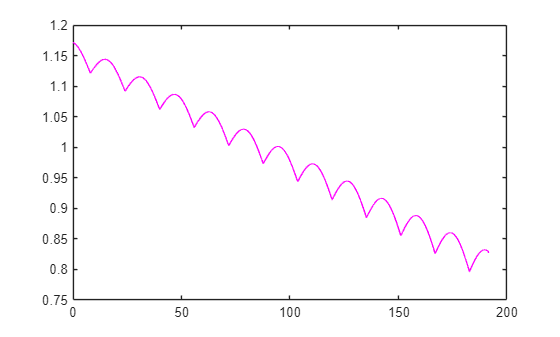

plot(tspan/3600, log(E_rs_upper), "m")

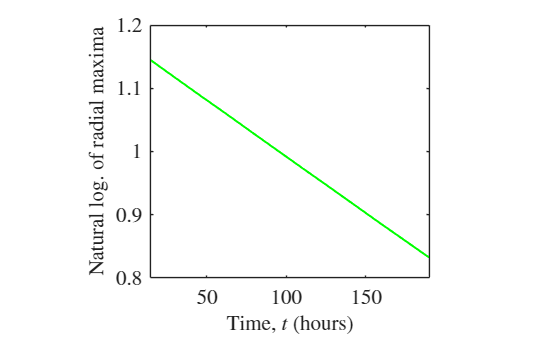

plot(tees/3600, log(rpeaks),"g", LineWidth = 1.5)
hold on 
ax = gca;
ax.TickLabelInterpreter = 'latex';
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16; 
if length(tees) > 1
    xlim([tees(1)/3600,tees(end)/3600])
end
xlabel("Time, $t$ (hours)", Interpreter = 'latex', FontSize = 16) 
ylabel("Natural log. of radial maxima", Interpreter = 'latex', FontSize = 16)
pbaspect([1.1 1 1]);

hold off


% Returns slope, intercept, half-life 
if length(tees) < 2
    logrslope = (log(E_rs_upper(end-10))-log(E_rs_upper(11)))/(tspan(end-10)-tspan(11))
    k = -logrslope
    halflife = log(2)/k
    halflife_hours = halflife/3600
    log(2)
else
    logrslope = (log(rpeaks(end))-log(rpeaks(1)))/(tspan(rlocs(end))-tspan(rlocs(1)))
    logrintercept = log(rpeaks(1)) 
    k = -logrslope
    A = exp(logrintercept)
    halflife = log(2)/(k)
    halflife_hours = halflife/3600 
end

logrslope =     -4.950884110920387e-07


logrintercept =    1.144272104315197


k =      4.950884110920387e-07


A =    3.140154819617023


halflife =      1.400047274447486e+06


halflife_hours =      3.889020206798572e+02




toc

Elapsed time is 156.250285 seconds.
